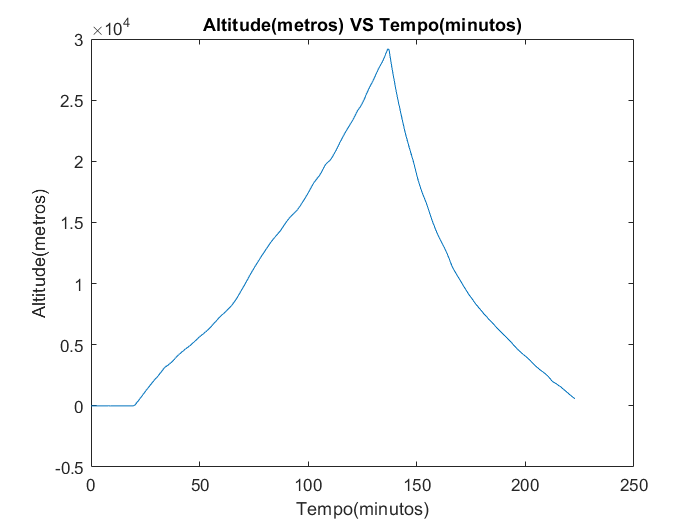

%Thestias Data Analysis

%Name of the data files
filenames = ["altitude.txt","extemp.txt","pressure.txt","temperature.txt","temperature2.txt"];

%Altitude analysis
altitude_data = importdata(filenames(1),",").data;
altitude_time = extractBetween(importdata(filenames(1),",").textdata,1,8);
altitude_time_minutes = date2timeCorrected(altitude_time);

figure()
plot(altitude_time_minutes,altitude_data)
title("Altitude(metros) VS Tempo(minutos)");
xlabel("Tempo(minutos)");
ylabel("Altitude(metros)");

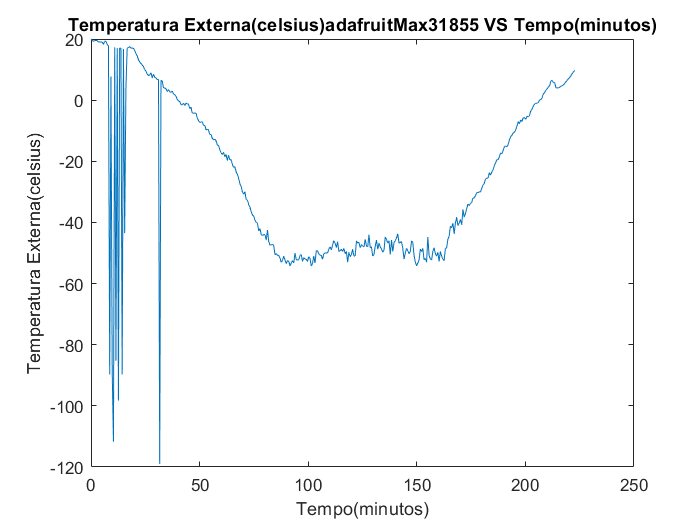


%External temperature analysis|adafruitMax31855
ext_temp_data = importdata(filenames(2),",").data;
ext_temp_time = extractBetween(importdata(filenames(2),",").textdata,12,19);
ext_temp_time_minutes = date2timeCorrected(ext_temp_time);

figure()
plot(ext_temp_time_minutes,ext_temp_data)
title("Temperatura Externa(celsius)adafruitMax31855 VS Tempo(minutos)");
xlabel("Tempo(minutos)");
ylabel("Temperatura Externa(celsius)");

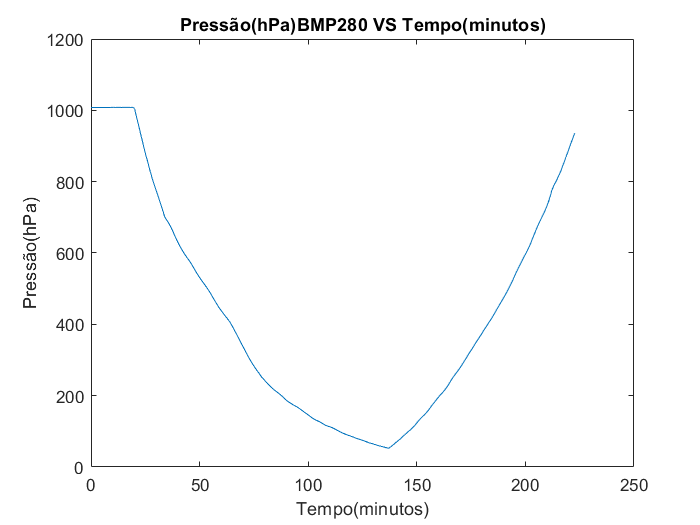


%Pressure analysis (HectoPascal)|BMP280
pressure_data = importdata(filenames(3),",").data;
pressure_time = extractBetween(importdata(filenames(3),",").textdata,12,19);
pressure_time_minutes = date2timeCorrected(pressure_time);

figure()
plot(pressure_time_minutes,pressure_data)
title("Pressão(hPa)BMP280 VS Tempo(minutos)");
xlabel("Tempo(minutos)");
ylabel("Pressão(hPa)");

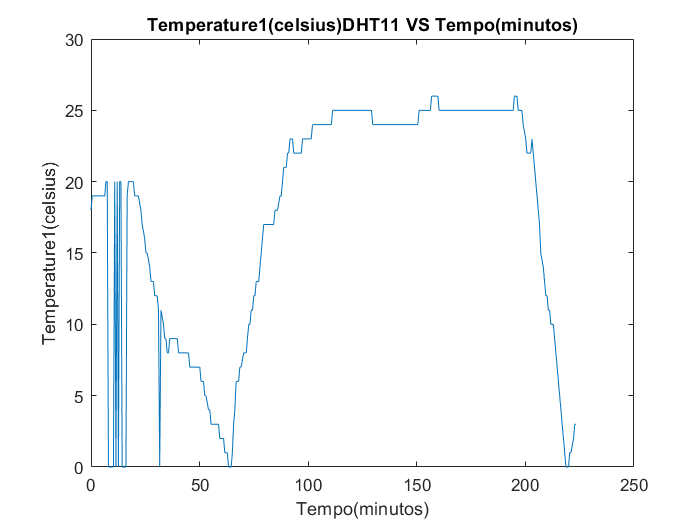


%Temperature1 analysis|DHT11
temperature1_data = importdata(filenames(4),",").data(:,1);
temperature1_time = extractBetween(importdata(filenames(4),",").textdata,12,19);
temperature1_time_minutes = date2timeCorrected(temperature1_time);

figure()
plot(temperature1_time_minutes,temperature1_data)
title("Temperature1(celsius)DHT11 VS Tempo(minutos)");
xlabel("Tempo(minutos)");
ylabel("Temperature1(celsius)");

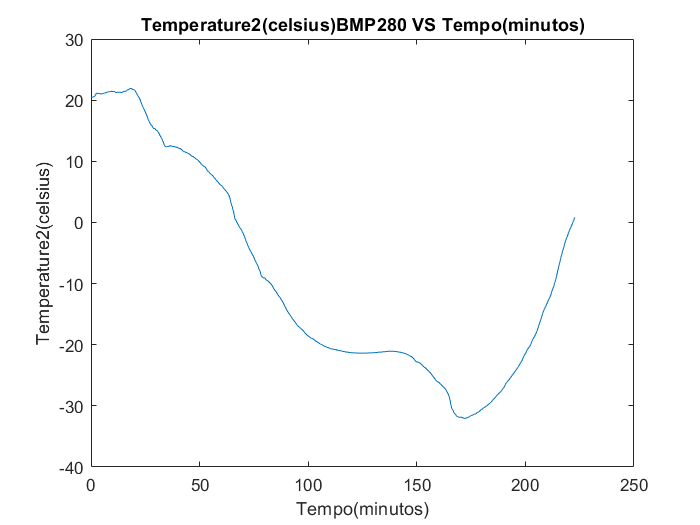


%Temperature2 analysis|BMP280
temperature2_data = importdata(filenames(5),",").data;
temperature2_time = extractBetween(importdata(filenames(5),",").textdata,12,19);
temperature2_time_minutes = date2timeCorrected(temperature2_time);

figure()
plot(temperature2_time_minutes,temperature2_data)
title("Temperature2(celsius)BMP280 VS Tempo(minutos)");
xlabel("Tempo(minutos)");
ylabel("Temperature2(celsius)");

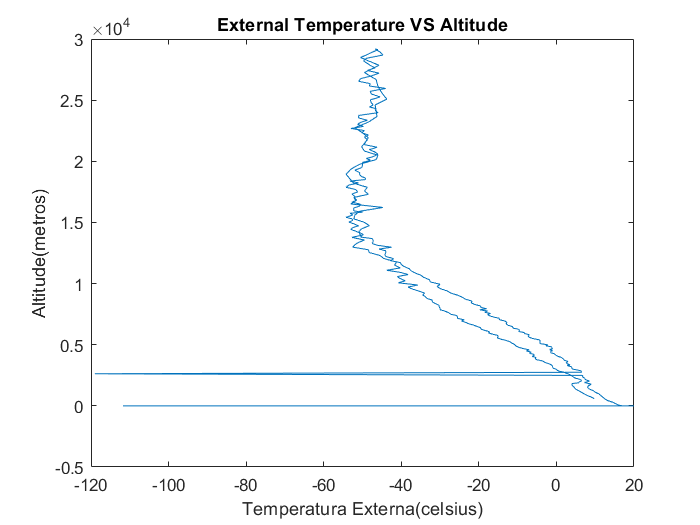


%External Temperature VS Altitude

figure()
plot(ext_temp_data,altitude_data)
title("External Temperature VS Altitude")
xlabel("Temperatura Externa(celsius)");
ylabel("Altitude(metros)");

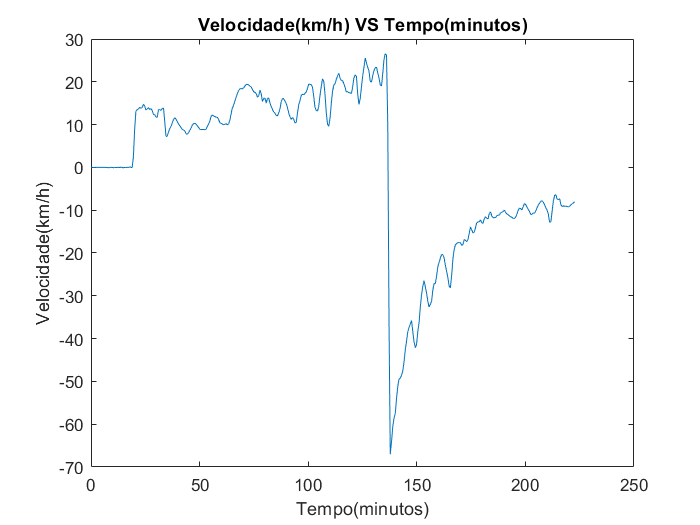



%Derivada de altitude vs tempo

velocidade = gradient(altitude_data(:)/1000) ./ gradient(altitude_time_minutes(:)/60);

figure()
plot(altitude_time_minutes,velocidade)
title("Velocidade(km/h) VS Tempo(minutos)")
xlabel("Tempo(minutos)");
ylabel("Velocidade(km/h)");

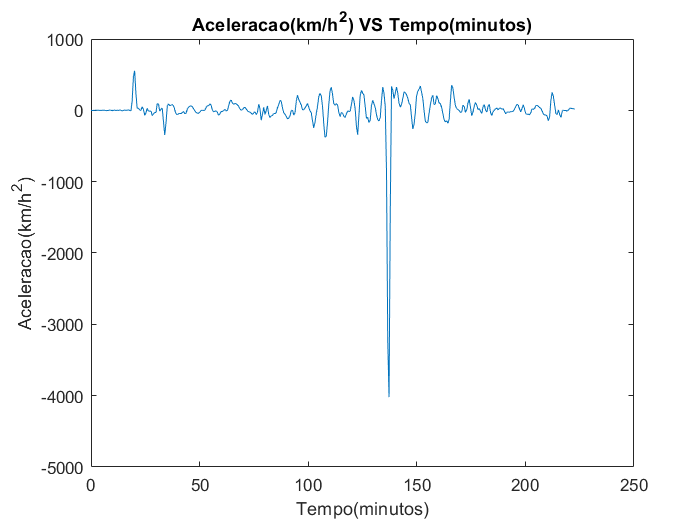


%Derivada de velocidade vs tempo

aceleracao = gradient(velocidade(:)) ./ gradient(altitude_time_minutes(:)/60);

figure()
plot(altitude_time_minutes,aceleracao)
title("Aceleracao(km/h^2) VS Tempo(minutos)")
xlabel("Tempo(minutos)");
ylabel("Aceleracao(km/h^2)");

function out = date2timeCorrected(array)
%Transforms from h:m:s to minutes since the start of measure
    array_length = size(array);
    out = zeros(array_length(1),1);
    for i = 1:array_length(1)
        hms = split(array(i),":");
        hours = str2num(cell2mat(hms(1)));
        minutes = str2num(cell2mat(hms(2)));
        seconds = str2num(cell2mat(hms(3)));
        out(i) = 60*60*hours + 60*minutes + seconds;
    end
    
   out = round((out - out(1))/60,2);
end